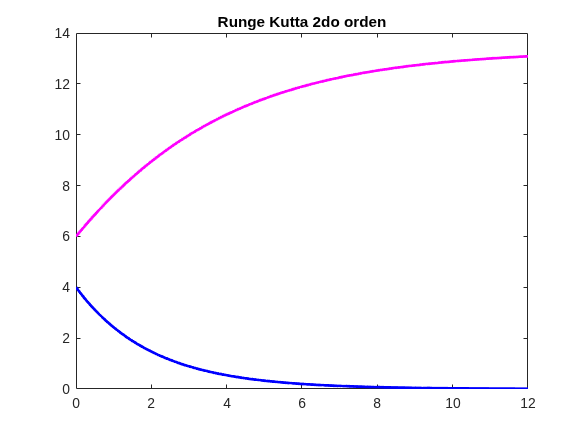

%Sistema de ecuaciones diferenciales
h = 0.025;
xin = 0;
xfin = 12;
x = xin:h:xfin;
nsteps = length(x);
y1 = zeros(1, nsteps);
y2 = zeros(1, nsteps);
%Creamos las funciones lado derecho de las ecuaciones diferenciales
d_y1 = @(ax, ay1, ay2) -0.5 * ay1;
d_y2 = @(ax, ay1, ay2) 4 - 0.3 * ay2 - 0.1 * ay1;
%Condiciones iniciales
x(1) = 0;
y1(1) = 4;
y2(1) = 6;
%Runge Kutta segundo orden
for i = 1 : nsteps - 1
    k1_y1 = d_y1(x(i), y1(i), y2(i));
    k1_y2 = d_y2(x(i), y1(i), y2(i));
    k2_y1 = d_y1(x(i) + h, y1(i) + k1_y1*h, y2(i) + k1_y2*h);
    k2_y2 = d_y2(x(i) + h, y1(i) + k1_y1*h, y2(i) + k1_y2*h);

    y1(i + 1) = y1(i) + 0.5 * (k1_y1 + k2_y1)*h;
    y2(i + 1) = y2(i) + 0.5 * (k1_y2 + k2_y2)*h;
end
%Graficamos los resultados
plot(x,y1,'-b', 'LineWidth',2)
hold on
plot(x,y2,'-m', LineWidth=2)
title("Runge Kutta 2do orden")
hold off

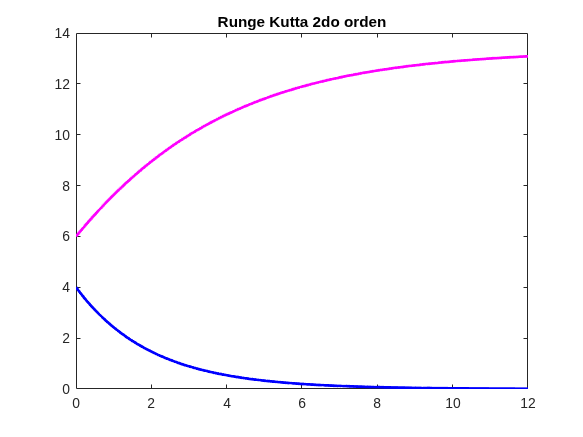


%Runge Kutta cuarto orden
for i = 1 : nsteps - 1
    k1_y1 = d_y1(x(i), y1(i), y2(i));
    k1_y2 = d_y2(x(i), y1(i), y2(i));

    k2_y1 = d_y1(x(i) + h * 0.5, y1(i) + k1_y1*h*0.5, y2(i) + k1_y2*h*0.5);
    k2_y2 = d_y2(x(i) + h * 0.5, y1(i) + k1_y1*h*0.5, y2(i) + k1_y2*h*0.5);
  
    k3_y1 = d_y1(x(i) + h * 0.5, y1(i) + k2_y1*h*0.5, y2(i) + k2_y2*h*0.5);
    k3_y2 = d_y2(x(i) + h * 0.5, y1(i) + k2_y1*h*0.5, y2(i) + k2_y2*h*0.5);
    
    k4_y1 = d_y1(x(i) + h, y1(i) + k3_y1 *h, y2(i) + k3_y2*h);
    k4_y2 = d_y2(x(i) + h, y1(i) + k3_y1 *h, y2(i) + k3_y2*h);



    y1(i + 1) = y1(i) + 1/6 * (k1_y1 + 2*k2_y1 + 2*k3_y1 + k4_y1)*h;
    y2(i + 1) = y2(i) + 1/6 * (k1_y2 + 2*k2_y2 + 2*k3_y2 + k4_y2)*h;
end

%Graficamos los resultados
plot(x,y1,'-b', 'LineWidth',2)
hold on
plot(x,y2,'-m', LineWidth=2)
title("Runge Kutta 2do orden")
hold off

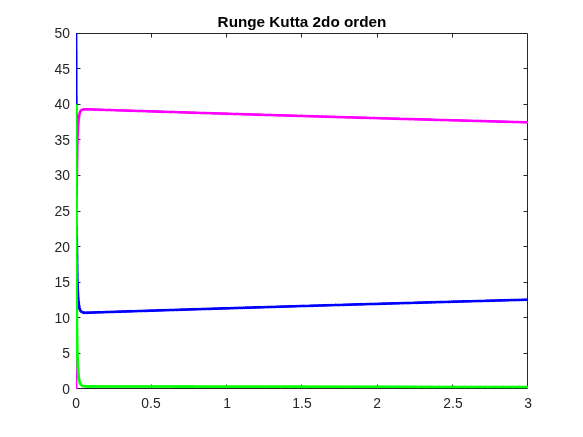

h = 0.00001;
tin = 0;
tfin = 3;
t = tin:h:tfin;
nsteps = length(t);
a = zeros(1, nsteps);
b = zeros(1, nsteps);
c = zeros(1, nsteps);
%Creamos las funciones lado derecho de las ecuaciones diferenciales
A = @(at, aa, ab, ac) -10*aa*ac + ab;
B = @(at, aa, ab, ac) 10*aa*ac - ab;
C = @(at, aa, ab, ac) -10*aa*ac + ab - 2*ac;
%Condiciones iniciales
a(1) = 50;
b(1) = 0;
c(1) = 40;
%Runge Kutta segundo orden
for i = 1 : nsteps - 1
    k1_a = A(t(i), a(i), b(i), c(i));
    k1_b = B(t(i), a(i), b(i), c(i));
    k1_c = C(t(i), a(i), b(i), c(i));

    k2_a = A(t(i) + h, a(i) + k1_a*h, b(i) + k1_b*h, c(i) + k1_c*h);
    k2_b = B(t(i) + h, a(i) + k1_a*h, b(i) + k1_b*h, c(i) + k1_c*h);
    k2_c = C(t(i) + h, a(i) + k1_a*h, b(i) + k1_b*h, c(i) + k1_c*h);
    
    a(i + 1) = a(i) + 0.5 * (k1_a + k2_a)*h;
    b(i + 1) = b(i) + 0.5 * (k1_b + k2_b)*h;
    c(i + 1) = c(i) + 0.5 * (k1_c + k2_c)*h;
end
%Graficamos los resultados
plot(t,a,'-b', 'LineWidth',2)
hold on
plot(t,b,'-m', LineWidth=2)
plot(t,c,'-g', LineWidth=2)
title("Runge Kutta 2do orden")
hold off

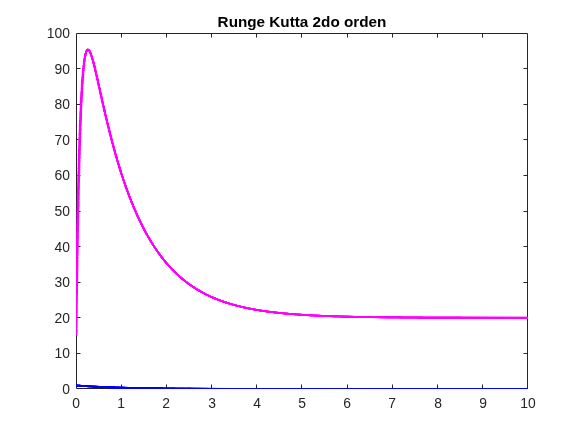

h = 0.001;
tin = 0;
tfin = 10;
t = tin:h:tfin;
nsteps = length(t);
c = zeros(1, nsteps);
temp = zeros(1, nsteps);
%Creamos las funciones lado derecho de las ecuaciones diferenciales
C = @(at, ac, atemp) -exp(-10/(atemp + 273)) * ac;
TEMP = @(at, ac, atemp) 1000 * exp(-10/(atemp + 273)) * ac - 10 * (atemp - 20);
%Condiciones iniciales
t(1) = 0;
c(1) = 1;
temp(1) = 15;
%Runge Kutta segundo orden
for i = 1 : nsteps - 1
    k1_c = C(t(i), c(i), temp(i));
    k1_temp = TEMP(t(i), c(i), temp(i));
    k2_c = C(t(i) + h, c(i) + k1_c*h, temp(i) + k1_temp*h);
    k2_temp = TEMP(t(i) + h, c(i) + k1_c*h, temp(i) + k1_temp*h);

    c(i + 1) = c(i) + 0.5 * (k1_c + k2_c)*h;
    temp(i + 1) = temp(i) + 0.5 * (k1_temp + k2_temp)*h;
end
%Graficamos los resultados
plot(t,c,'-b', 'LineWidth',2)
hold on
plot(t,temp,'-m', LineWidth=2)
title("Runge Kutta 2do orden")
hold off